# Experieência 1 - LMS com Sinais Senoidais

## Gabriel Tavares Ferrarez - 10773801

## Guilherme Reis da Silva - 10773700

1 - Criação dos Sinais

omega0 = pi/6;
omega1 = pi/20;
N = 10000;
n = (0:N-1);
x = sin(omega0*n);
v = cos(omega1*n);
h = [1 -0.5];

y = filter(h,1,x);
d = y + v;

%TODO colocar os sinais em subplots

2 - Implementação do LMS

mu = 0.01;
M = 2;

[W, erro, y_chapeu] = lms(x, d, M, mu);

Potencia do Erro

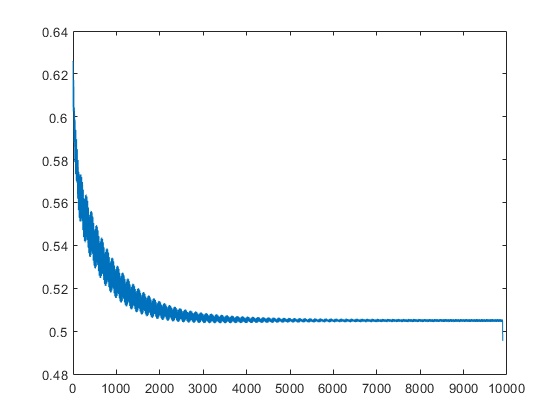

pot_erro = erro.*erro;
mediaMovel = (1/100)*ones(100,1);
pot_erro_filt = filter(mediaMovel,1,pot_erro);
plot(pot_erro_filt(100:end));

Sinais de erro

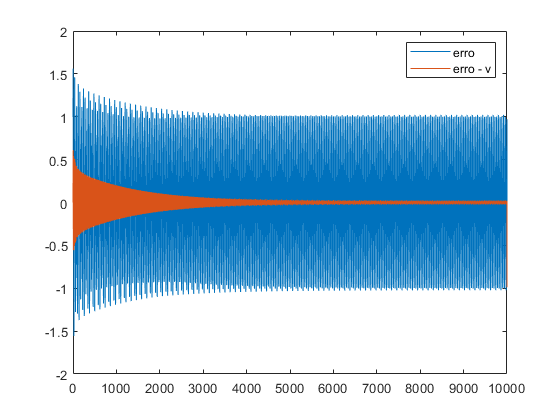

plot(erro)
hold on
plot(erro - v)
hold off
legend("erro", "erro - v")

Convergencia de coeficientes

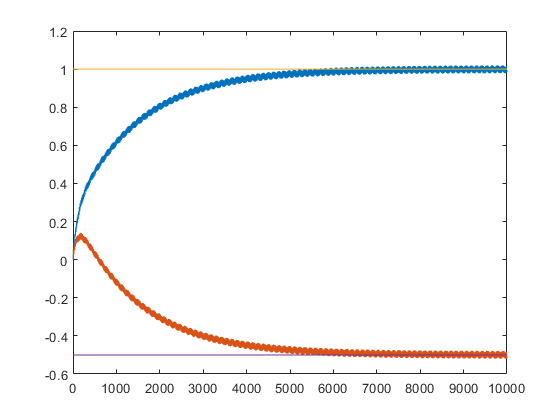

plot(W')
hold on
plot([0 N],[h(1) h(1)])
plot([0 N],[h(2) h(2)])
hold off

3 - Novo w0

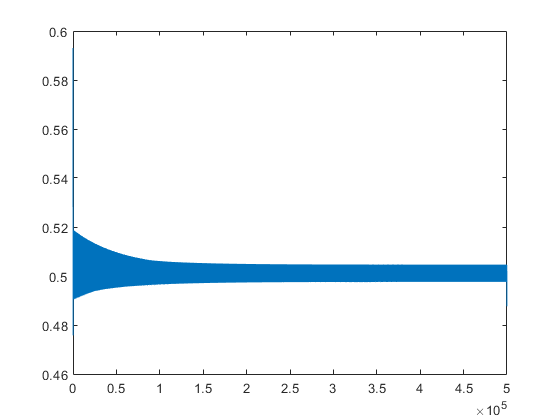

omega0 = pi/40;
N = 5e5;
n = (0:N-1);

x = sin(omega0*n);
v = cos(omega1*n);

y = filter(h,1,x);
d = y + v;

mu = 0.01;
[W, erro, y_chapeu] = lms(x, d, M, mu);

pot_erro = erro.*erro;
mediaMovel = (1/100)*ones(100,1);
pot_erro_filt = filter(mediaMovel,1,pot_erro);
plot(pot_erro_filt(100:end));

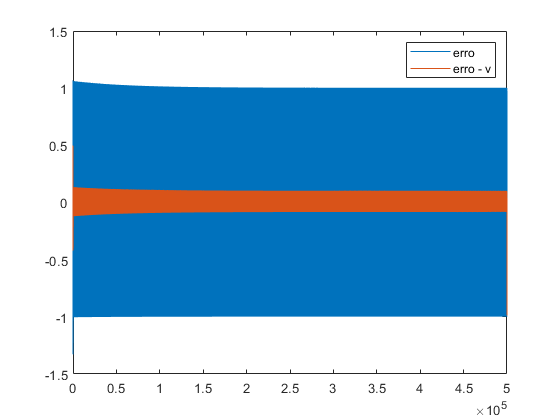


plot(erro)
hold on
plot(erro - v)
hold off
legend("erro", "erro - v")

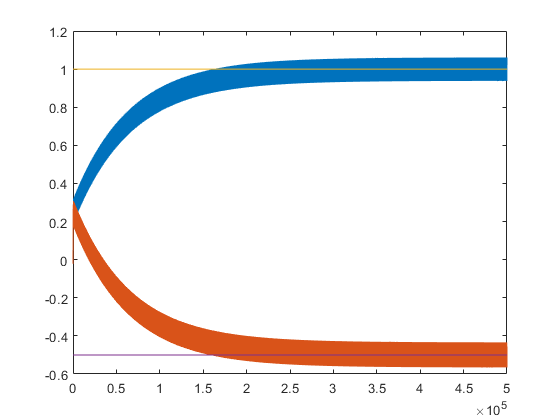


plot(W')
hold on
plot([0 N],[h(1) h(1)])
plot([0 N],[h(2) h(2)])
hold off

4 - Filtro com 3 coeficientes

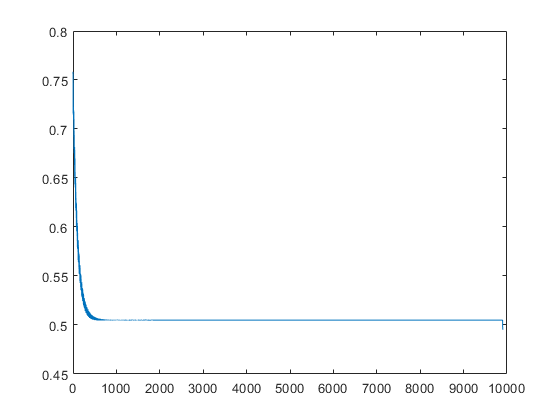

omega0 = pi/2;
omega1 = pi/20;
N = 1e4;
n = (0:N-1);
x = sin(omega0*n);
v = cos(omega1*n);
h = [1 -0.5 0.3];

y = filter(h,1,x);
d = y + v;

%TODO colocar os sinais em subplots

mu = 0.01;
M = 2;

[W, erro, y_chapeu] = lms(x, d, M, mu);

pot_erro = erro.*erro;
mediaMovel = (1/100)*ones(100,1);
pot_erro_filt = filter(mediaMovel,1,pot_erro);
plot(pot_erro_filt(100:end));

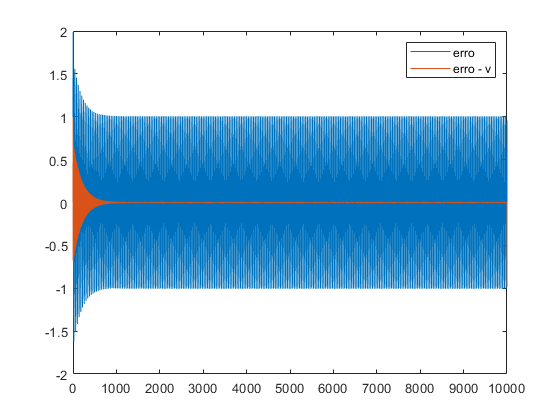


plot(erro)
hold on
plot(erro - v)
hold off
legend("erro", "erro - v")

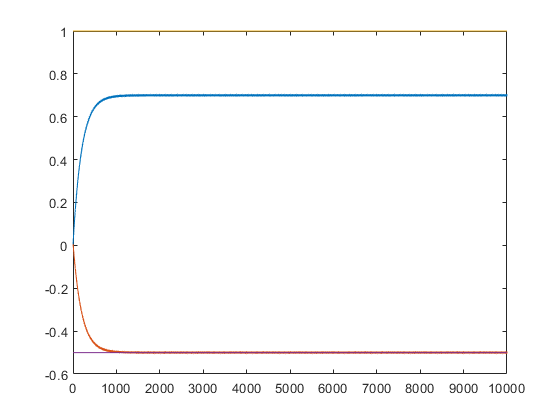


plot(W')
hold on
plot([0 N],[h(1) h(1)])
plot([0 N],[h(2) h(2)])
hold off

%TODO fazer a conta dos coeficientes teoricos

5 - Ganho dos filtros H e W

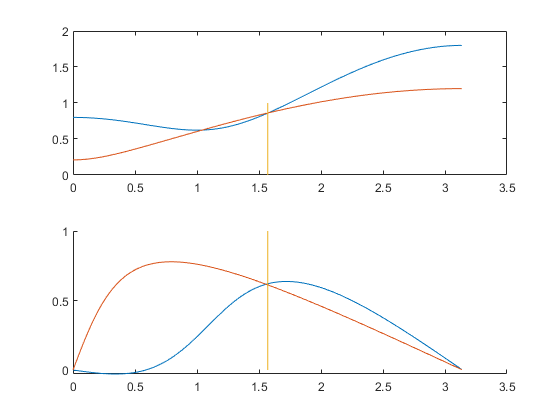

[H, omeguinha] = freqz(h);
[Wzao, omeguinhaW] = freqz(W(:,end));

figure()
subplot(2,1,1)
plot(omeguinha, abs(H))
hold on
plot(omeguinhaW, abs(Wzao))
plot([omega0 omega0], [0 1])
hold off
subplot(2,1,2)
hold on
plot(omeguinha, angle(H))
plot(omeguinhaW, angle(Wzao))
plot([omega0 omega0], [0 1])
hold off

6 - sinal de x modificado

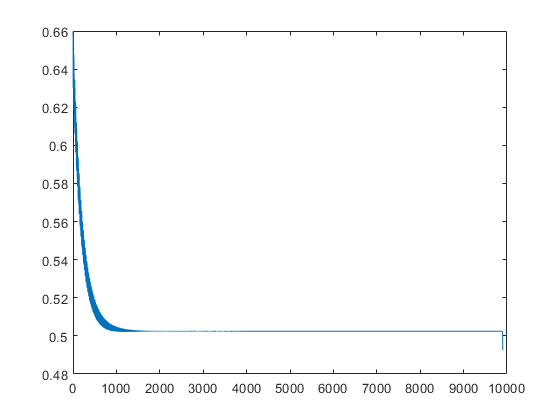

omega0 = pi/2;
omega1 = pi/20;
N = 1e4;
n = (0:N-1);
x = sin(omega0*n) + 0.3*sin(3*omega0*n);
v = cos(omega1*n);
h = [1 -0.5 0.3];

y = filter(h,1,x);
d = y + v;

%TODO colocar os sinais em subplots

mu = 0.01;
M = 2;

[W, erro, y_chapeu] = lms(x, d, M, mu);

pot_erro = erro.*erro;
mediaMovel = (1/100)*ones(100,1);
pot_erro_filt = filter(mediaMovel,1,pot_erro);

figure()
plot(pot_erro_filt(100:end));

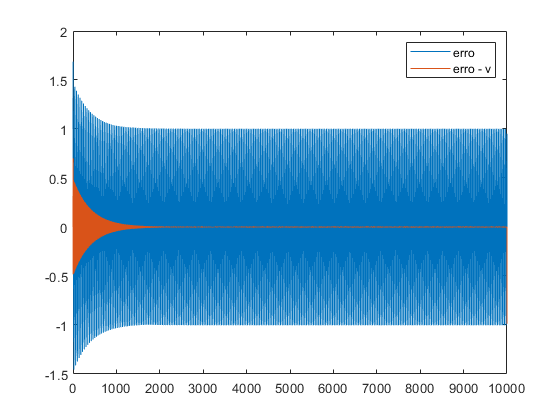

figure()
plot(erro)
hold on
plot(erro - v)
hold off
legend("erro", "erro - v")

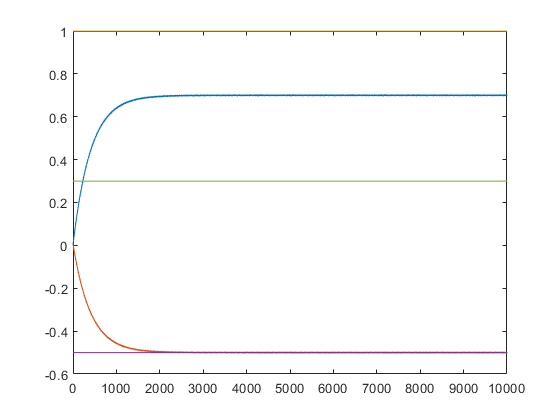

figure()
plot(W')
hold on
plot([0 N],[h(1) h(1)])
plot([0 N],[h(2) h(2)])
plot([0 N],[h(3) h(3)])
hold off

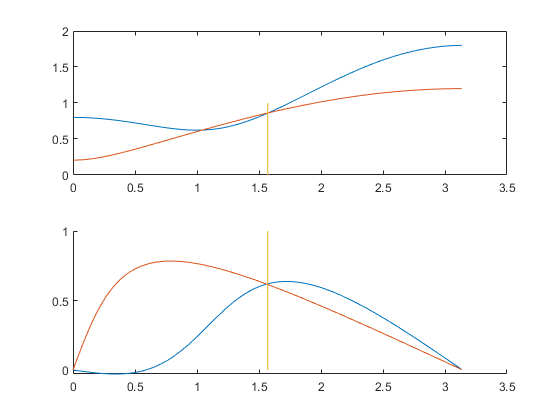


[H, omeguinha] = freqz(h);
[Wzao, omeguinhaW] = freqz(W(:,end));

figure()
subplot(2,1,1)
plot(omeguinha, abs(H))
hold on
plot(omeguinhaW, abs(Wzao))
plot([omega0 omega0], [0 1])
hold off
subplot(2,1,2)
hold on
plot(omeguinha, angle(H))
plot(omeguinhaW, angle(Wzao))
plot([omega0 omega0], [0 1])
hold off